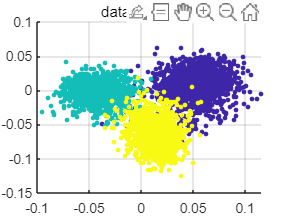

X = data';
ns = 4500;
nf = 784;
targetdim = 2;
lambda=1e-3; %正则化参效
%计算总体散布矩阵
X_ave = mean(X);
st = (X - X_ave)' * (X - X_ave);
C1 =X(1:1500,:);
C2 = X(1501:3000,:);
C3 = X(3000:4500,:);
% 计算均值
xC1 = mean(C1);
xC2 = mean(C2);
xC3 = mean(C3);
% 计算类内教布矩阵
sC1 = (C1 - xC1)'*(C1- xC1);
sC2 = (C2 - xC2)'*(C2 - xC2);
sC3 = (C3 - xC3)'*(C3 - xC3);
% 计算类间教布矩阵
sw = sC1 + sC2 + sC3 + lambda * eye(nf);
sb=st - sw;
%计算 (S w)~(-1) * s b
%s = inv(s_w) * s b;
s = sw \sb;
% 特征值分解
[eigvec, eigwal] = eig(s);
%投影数据
[~, sortedindices] = sort(diag(eigwal), 'descend');
eigvec = eigvec(:, sortedindices(1:targetdim));
Xldaself = X * eigvec;
 %可视化

scatter(Xldaself(:, 1), Xldaself(:, 2),10,groundTruth,'filled');
title('LDA Projection');
grid on
X_reduced = Xldaself;
title('data after LDA');

kmeans 聚类

k = 3; % 聚类的数量
[cluster_labels, ~] = kmeans(X_reduced, k);
% 绘制kmeans的聚类结果
silhouette_hierarchical = silhouette(X_reduced, cluster_labels);
avg_silhouette_hierarchical = mean(silhouette_hierarchical);
disp(['kmean聚类的平均轮廓系数: ', num2str(avg_silhouette_hierarchical)]);

kmean聚类的平均轮廓系数: 0.9122


true_labels = groundTruth;
% 假设 cluster_labels 和 true_labels 已经准备好
% 这里 cluster_labels 是聚类后的标签，true_labels 是真实标签

% 获取唯一的聚类标签列表
unique_cluster_labels = unique(cluster_labels);

% 初始化映射关系的容器
mapping = zeros(size(unique_cluster_labels));

% 获取唯一的真实标签
unique_true_labels = unique(true_labels);

% 遍历每个聚类标签
for i = 1:length(unique_cluster_labels)
    current_cluster_label = unique_cluster_labels(i);
    
    % 找出当前聚类标签对应的所有样本点
    indices = cluster_labels == current_cluster_label;
    
    % 获取这些样本点的真实标签
    current_true_labels = true_labels(indices);
    
    % 统计当前聚类中每个真实标签的出现次数
    label_counts = histc(current_true_labels, unique_true_labels);
    
    % 选择出现次数最多的真实标签作为映射
    [~, max_count_idx] = max(label_counts);
    mapping(i) = unique_true_labels(max_count_idx);
end

% 显示映射结果
disp(mapping);

     3
     1
     2



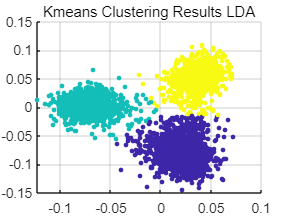


% 假设 cluster_labels、true_labels 和 mapping 已经准备好

% 创建一个新的数组来存储重新贴标签的结果
relabelled_cluster_labels = zeros(size(cluster_labels));

% 获取唯一的聚类标签列表
unique_cluster_labels = unique(cluster_labels);

% 遍历所有数据点
for i = 1:length(cluster_labels)
    % 获取当前数据点的聚类标签
    current_cluster_label = cluster_labels(i);
    
    % 找到当前聚类标签在 unique_cluster_labels 中的索引
    cluster_label_index = find(unique_cluster_labels == current_cluster_label);

    % 获取映射后的真实标签
    mapped_label = mapping(cluster_label_index);

    % 更新重新贴标签的数组
    relabelled_cluster_labels(i) = mapped_label;
end

% 显示重新贴标签的结果

figure;
scatter(X_reduced(:, 1), X_reduced(:, 2), 10, relabelled_cluster_labels, 'filled');
title('Kmeans Clustering Results LDA');
grid on

accuracy = sum(groundTruth == relabelled_cluster_labels) / length(groundTruth);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 98.98%


层次聚类

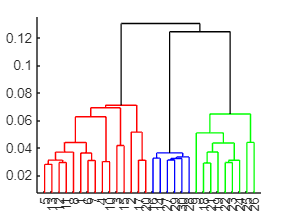

% 使用层次聚类进行聚类
Z = linkage(X_reduced, 'average','euclidean');

cluster_idx_hierarchical = cluster(Z,'maxclust', 3);
cutoff = median([Z(end-2,3) Z(end-1,3)]);
dendrogram(Z,'ColorThreshold',cutoff)


true_labels = groundTruth;
cluster_labels =cluster_idx_hierarchical;
% 假设 cluster_labels 和 true_labels 已经准备好
% 这里 cluster_labels 是聚类后的标签，true_labels 是真实标签

% 获取唯一的聚类标签列表
unique_cluster_labels = unique(cluster_labels);

% 初始化映射关系的容器
mapping = zeros(size(unique_cluster_labels));

% 获取唯一的真实标签
unique_true_labels = unique(true_labels);

% 遍历每个聚类标签
for i = 1:length(unique_cluster_labels)
    current_cluster_label = unique_cluster_labels(i);
    
    % 找出当前聚类标签对应的所有样本点
    indices = cluster_labels == current_cluster_label;
    
    % 获取这些样本点的真实标签
    current_true_labels = true_labels(indices);
    
    % 统计当前聚类中每个真实标签的出现次数
    label_counts = histc(current_true_labels, unique_true_labels);
    
    % 选择出现次数最多的真实标签作为映射
    [~, max_count_idx] = max(label_counts);
    mapping(i) = unique_true_labels(max_count_idx);
end

% 显示映射结果
disp(mapping);

     3
     2
     1




% 假设 cluster_labels、true_labels 和 mapping 已经准备好

% 创建一个新的数组来存储重新贴标签的结果
relabelled_cluster_labels = zeros(size(cluster_labels));

% 获取唯一的聚类标签列表
unique_cluster_labels = unique(cluster_labels);

% 遍历所有数据点
for i = 1:length(cluster_labels)
    % 获取当前数据点的聚类标签
    current_cluster_label = cluster_labels(i);
    
    % 找到当前聚类标签在 unique_cluster_labels 中的索引
    cluster_label_index = find(unique_cluster_labels == current_cluster_label);

    % 获取映射后的真实标签
    mapped_label = mapping(cluster_label_index);

    % 更新重新贴标签的数组
    relabelled_cluster_labels(i) = mapped_label;
end

% 显示重新贴标签的结果



figure;
silhouette_hierarchical = silhouette(X_reduced, relabelled_cluster_labels);
avg_silhouette_hierarchical = mean(silhouette_hierarchical);
disp(['层次聚类的平均轮廓系数: ', num2str(avg_silhouette_hierarchical)]);

层次聚类的平均轮廓系数: 0.90782


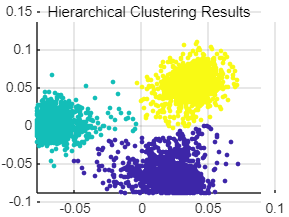

% 绘制层次聚类的聚类结果
figure;
scatter(X_reduced(:, 1), X_reduced(:, 2), 10, relabelled_cluster_labels, 'filled');
title('Hierarchical Clustering Results'); 
grid on

accuracy = sum(groundTruth == relabelled_cluster_labels) / length(groundTruth);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 98.91%
